# Compare Airspeed

## Load SF data

SF = readtable('SF/Track.csv');
SF.Code = categorical(SF.Code);

Convert speed in complex

SF.ground = SF.Vg/100 .* exp( mod(-deg2rad(SF.Rg)+90,360)*1i );
SF.wind   = SF.Vw/100 .* exp( mod(-deg2rad(SF.Rw)+90,360)*1i );
SF.air    = SF.Va/100 .* exp( mod(-deg2rad(SF.Ra)+90,360)*1i ); 

Add seasonal variables

season = [50 175 320 Inf]; % day of year
season_label = {'Spring (20-Feb  - 25-June)','Autumn (25-June - 17-Nov)','Winter (17-Nov - 20-Feb)'};
SF.season=sum(bsxfun(@gt, day(SF.Date,'dayofyear'), season),2);
SF.season(SF.season==0)=4;

Define parameter of histogram

norm = 'pdf';
edge_angle=32;
edge_hist = 0:40;

## Initial Visualization of Dataset

Date

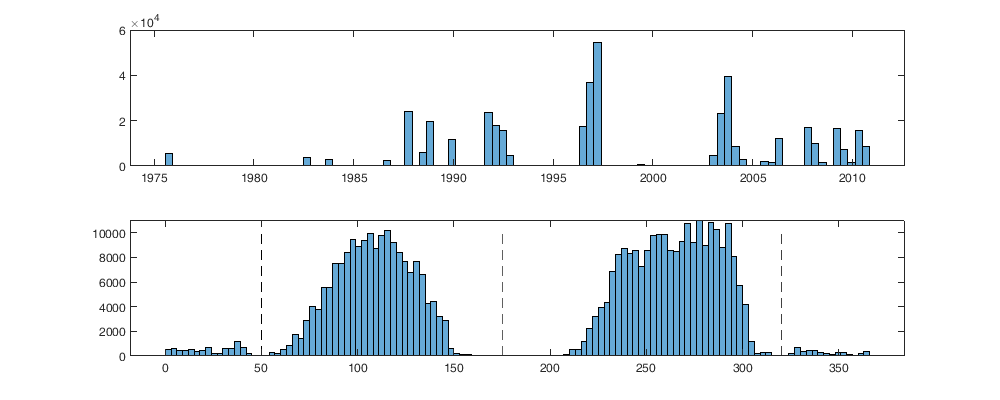

figure('position',[0 0 1000 400]);
subplot(2,1,1); histogram(SF.Date)
subplot(2,1,2); histogram(day(SF.Date,'dayofyear')); hold on;
plot([season; season],[0 10000],'--k')

Speed

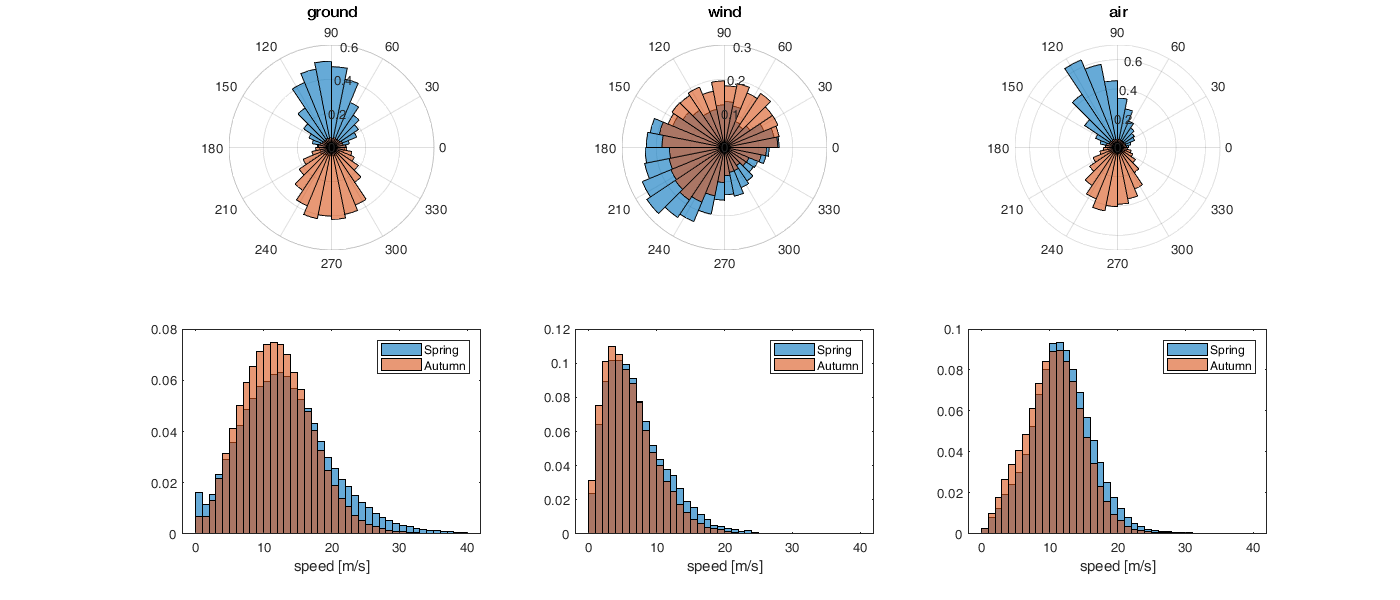

l = {'ground','wind','air'};
s = [1 2];
figure('position',[0 0 1400 600])
for i_l=1:numel(l)
    for i_s=1:numel(s)
        subplot(2,3,i_l)
        polarhistogram(angle(SF.(l{i_l})(SF.season==s(i_s))),edge_angle,'Normalization',norm); hold on;
        title(l{i_l});
        subplot(2,3,i_l+numel(l))
        histogram(abs(SF.(l{i_l})(SF.season==s(i_s))),edge_hist,'Normalization',norm); hold on;
    end
    legend({'Spring','Autumn'}); xlabel('speed [m/s]')
end

## Nighly average

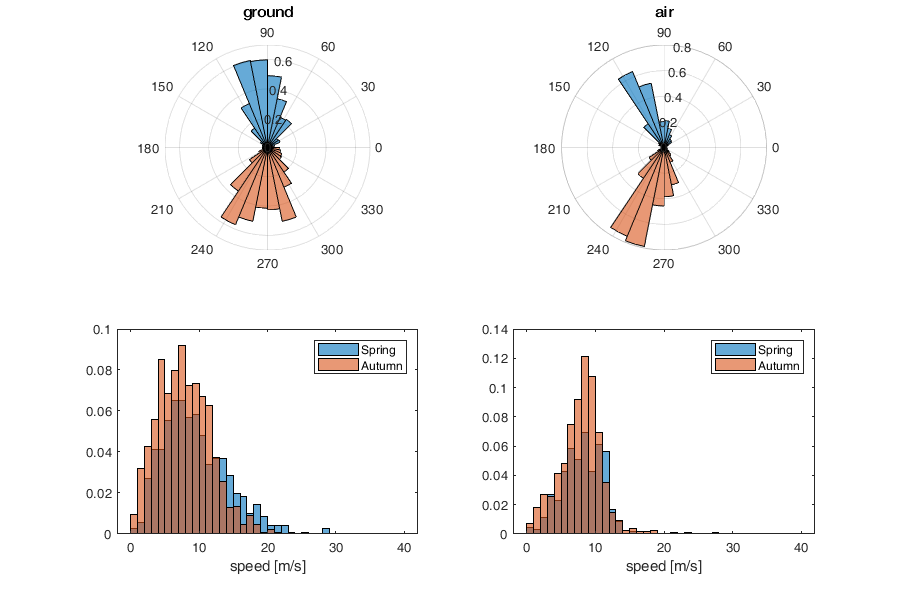

VWR = 1.8850e+03

VBS = 0.0130

ans = 12.5805

ans = 6.2903

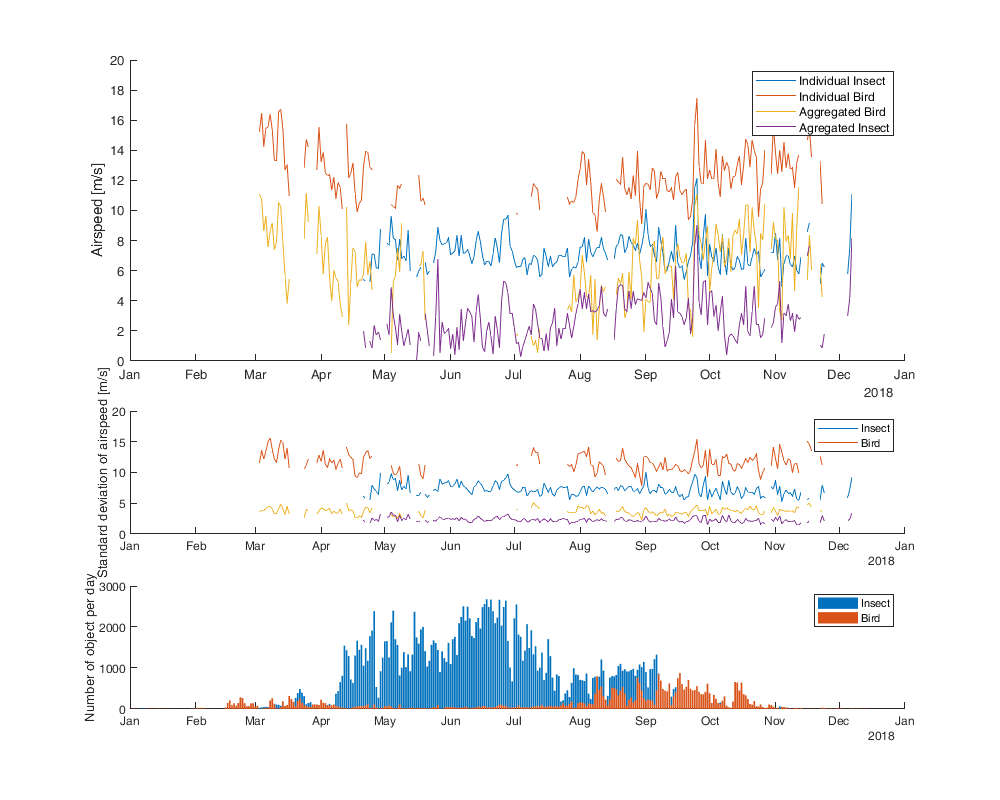

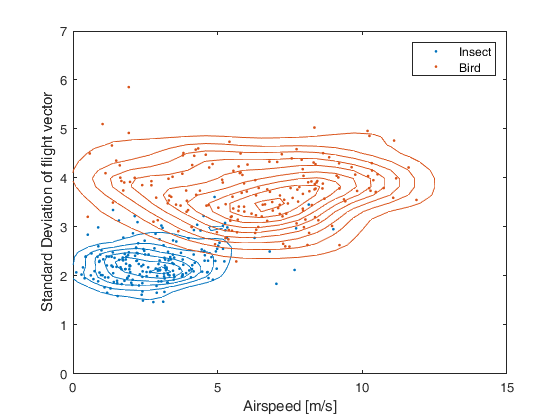

l = {'ground','air'};
s = [1 2];

figure('position',[0 0 900 600])
for i_l=1:numel(l)
    for i_s=1:numel(s)
        [G,G_date, G_code] = findgroups(dateshift(SF.Date(SF.season==s(i_s)),'start','day') , SF.Code(SF.season==s(i_s)));
        tmp = splitapply(@mean, SF.(l{i_l})(SF.season==s(i_s)), G);
        
        subplot(2,2,i_l)
        polarhistogram(angle(tmp),edge_angle,'Normalization',norm); hold on;
        title(l{i_l});
        subplot(2,2,i_l+numel(l))
        histogram(abs(tmp),edge_hist,'Normalization',norm); hold on;
    end
    legend({'Spring','Autumn'}); xlabel('speed [m/s]')
end